# Fit of baseline and phase corrected data EDMR-on-chip

clearvars, clear, clc, close all
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));

Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\New chip';
Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';

## Start of expansion to every spectrum

load([Opt.LFolder, '\fit_chip_parfor_m_param.mat']);
[nm, ncw] = size(par);


## m = 1 is the same as not smoothened data.

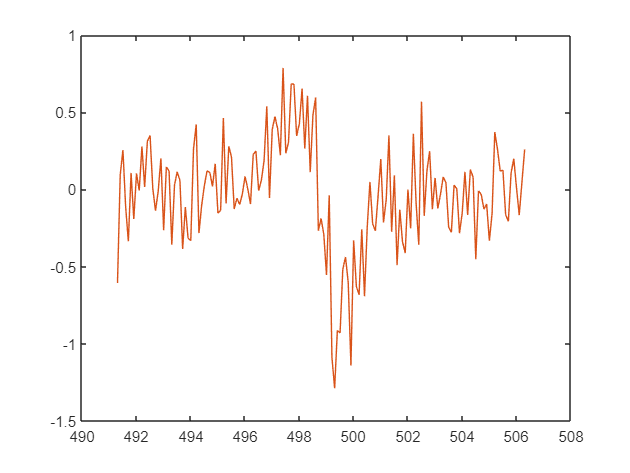

figure()
x_ = par(1, 1).x; y_ = par(1, 1).y;
plot(x_, y_)
hold on
plot(x_, datasmooth(y_, 1, 'savgol'))

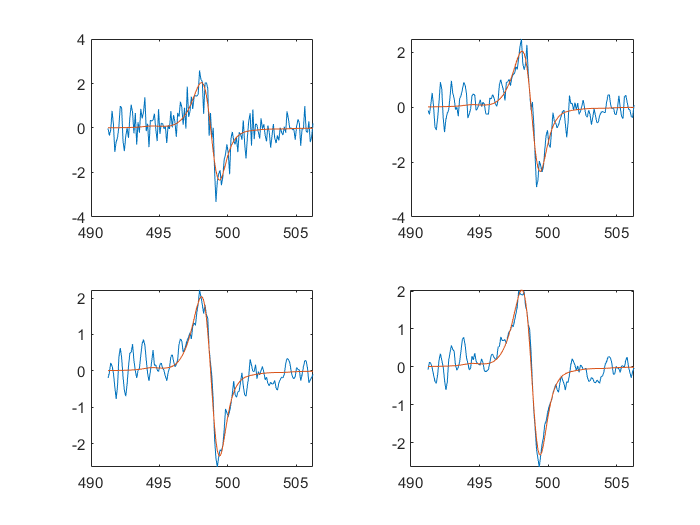

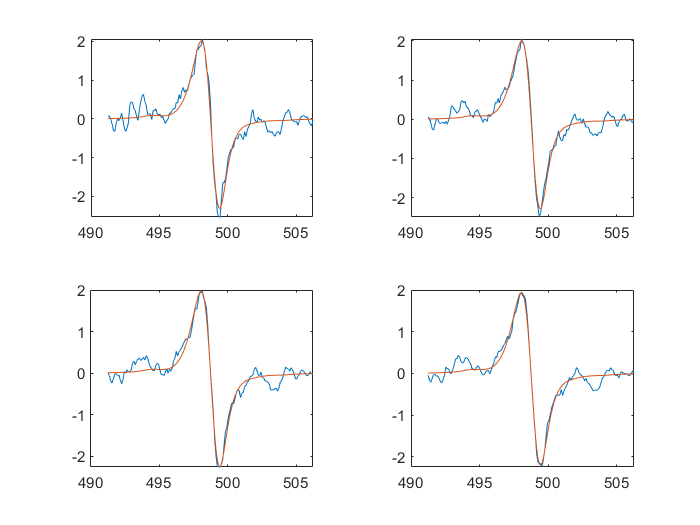

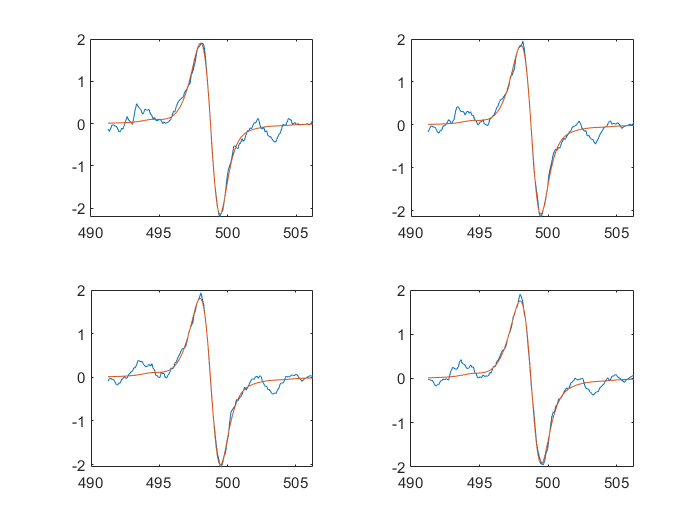

figure()

nFig = 3;
nTile = nm/nFig;
icw = 4;
for iFig = 1:nFig
    figure()
    tiledlayout(2,2)
    for iTile = 1:nTile
        nexttile
        plot(par(iTile + (iFig - 1)*nTile, icw).x, par(iTile + (iFig - 1)*nTile, icw).y)
        hold on
        plot(par(iTile + (iFig - 1)*nTile, icw).x, par(iTile + (iFig - 1)*nTile, icw).Fit.fit)
    end
end

## m = 4 is dlw similar to 1% for all the spectra

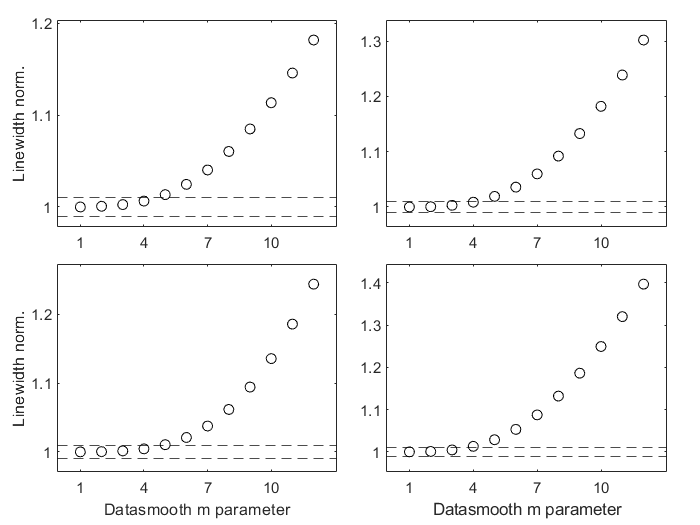

grayC = '#b2beb5';
figure()
tL = tiledlayout(2,2, 'TileSpacing', 'compact', 'Padding', 'compact');
for icw = 1:ncw
    for im = 1:nm
        lw(im) = par(im, icw).Fit.pfit(1);
    end
    nexttile;
    plot(1:12, lw/lw(1), 'o', 'Color', 'black')
    xlim(setAxLim(1:12, 0.1)); ylim(setAxLim(lw/lw(1), 0.12))
    yline(1.01, '--', 'Color', 'black'); yline(0.99, '--', 'Color', 'black');
    xticks(1:3:12); yticks(1:0.1:1.4);
end
labelAxesFig(tL, 'Datasmooth m parameter', 'Linewidth norm.')
exportFig(gcf, Opt.SFolder, '\Lw vs m', 'png', 'lw vs m')

## Interpolation

x_ = par(1, 1).x; y_ = par(1, 1).y;
F = griddedInterpolant(x_, y_);

F =   griddedInterpolant with properties:

            GridVectors: {[151×1 double]}
                 Values: [151×1 double]
                 Method: 'linear'
    ExtrapolationMethod: 'linear'


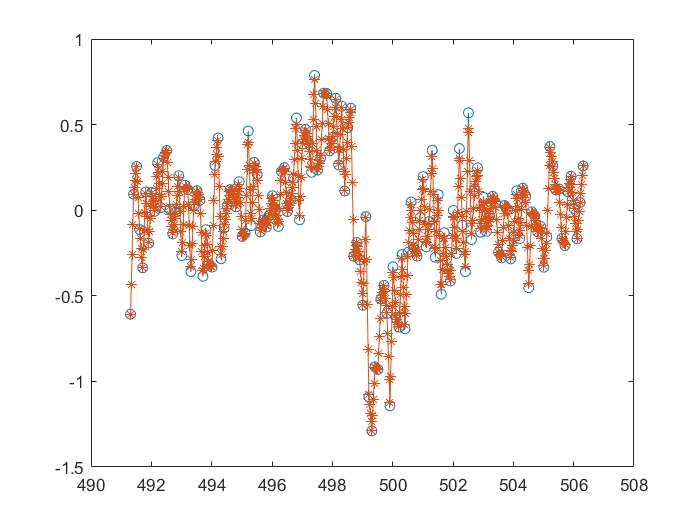

xq = linspace(min(x_), max(x_), 4*numel(x_) - 1);
yq = F(xq);
figure()
plot(x_, y_, 'o-')
hold on
plot(xq, yq, '*-')

#### Spin systems

SysDb = struct(g = [2.0079 2.0061 2.0034], ...
    gStrain = [0.0054 0.0022 0.0018], ...
    lw = [0. 1.3], ...
    Nucs = 'Si', A = [151 269], ...
    FieldOffset = -1.2);
VaryDb = struct( ...
    lw = SysDb.lw, ...
    FieldOffset = 2);

SysV = struct(g = 2.01, ...
    gStrain = 0.0098, ...
    lw = [1. 0.55], ...
    weight = 0.3);
VaryV = struct( ...
    lw = SysV.lw, ...
    weight = SysV.weight);

Exp.mwFreq = 14; % GHz

% Sys = {SysDb, SysV};
% Vary = {VaryDb, VaryV};

## Field offset for fit with two spin systems

*pepperFieldOffset *does not work with more than 1 spin system. Correction is done shifting the magnetic field array, then the shift is checked again after the fitting.

Since we noticed that one spin system fits the data well, below I fit with *pepperFieldOffset* directly and then correct the data after the fit.

Sys = SysDb;
Vary = VaryDb;

Exp.nPoints = numel(x_); Exp.Range = [min(x_) max(x_)];
FitNormale = esfit(y_, @pepperFieldOffset, {Sys, Exp}, {Vary});

-- esfit ------------------------------------------------
Data size:                [151, 1]
Model function name:      pepperFieldOffset
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
** Spectrum exceeds sweep range. Artifacts at lower limit possible.
** Spectrum exceeds sweep range. Artifacts at lower limit possible.
** Spectrum exceeds sweep range. Artifacts at lower limit possible.
iteration   1: value 3.33303e-01   edge 1.00000e-01   initial simplex
** Spectrum exceeds sweep range. Artifacts at lower limit possible.
iteration   2: value 3.02540e-01   edge 6.00000e-01   expansion
iteration   3: value 2.46829e-01   edge 6.00000e-01   reflection
iteration   4: value 2.34067e-01   edge 6.00000e-01   reflection
iteration   5: value 2.34067e-01   edge 3.90000e-01   contraction outs

Exp.nPoints = numel(xq); Exp.Range = [min(xq) max(xq)];
FitDenso = esfit(yq, @pepperFieldOffset, {Sys, Exp}, {Vary});

-- esfit ------------------------------------------------
Data size:                [1, 603]
Model function name:      pepperFieldOffset
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
** Spectrum exceeds sweep range. Artifacts at lower limit possible.
** Spectrum exceeds sweep range. Artifacts at lower limit possible.
** Spectrum exceeds sweep range. Artifacts at lower limit possible.
iteration   1: value 3.02135e-01   edge 1.00000e-01   initial simplex
** Spectrum exceeds sweep range. Artifacts at lower limit possible.
iteration   2: value 2.67712e-01   edge 6.00000e-01   expansion
iteration   3: value 2.02654e-01   edge 6.00000e-01   reflection
iteration   4: value 1.86758e-01   edge 6.00000e-01   reflection
iteration   5: value 1.86758e-01   edge 3.90000e-01   contraction outs

Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\New chip';
saveStr = input('Export data to .mat file? y/n\n', 's');
if strcmp(saveStr, 'y')
    cwStruct = cw.cwStruct;
    save([Opt.SFolder, '\fit_chip'], 'x', 'y', 'cwStruct', 'Fit');
    % exportgraphics(gcf, [Opt.SFolder, '/2022-06-17 cwEDMR forward bias.png'])
else
    disp('Data not exported')
end

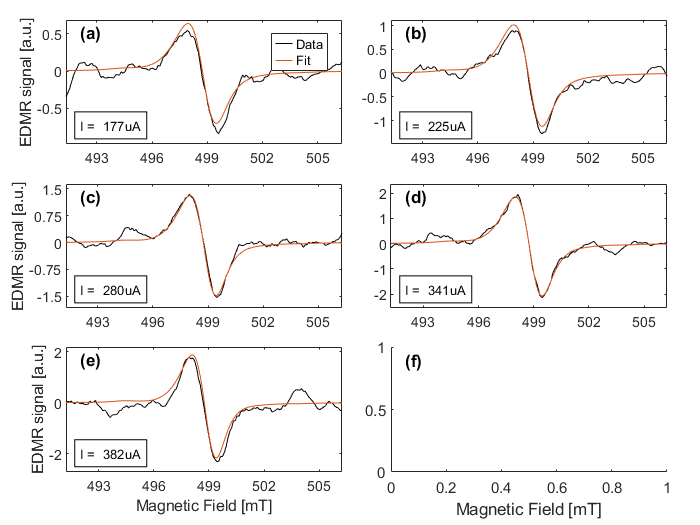

figure()
tL = tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact');
for icw = 1:ncw
    nexttile
    x_ = x(:, icw); y_ = y(:, icw); yFit_ = Fit(icw).fit;
    h(1) = plot(x_, y_, 'Color', 'black');
    hold on
    h(2) = plot(x_, yFit_);

    xticks(493:3:508);
    xlim(setAxLim(x_, 0)); ylim(setAxLim(y_, 0.1));

    % title(cw(icw).Title)
    annStr = {sprintf('I = %s', cwStruct(icw).Title(end-5:end))};
    text(0.05, 0.15, annStr, 'Units', 'normalized', ...
        'FontSize', 8, ...
        'BackgroundColor', 'white', ...
        'EdgeColor', 'black');
end
nexttile(2); yticks(-1:.5:1);
nexttile(3); yticks(-1.5:.75:1.5);
nexttile(4); yticks(-2:1:2);
annotateSubplotId(tL)
labelAxesFig(tL, "Magnetic Field [mT]", "EDMR signal [a.u.]")
lgd = legendFirstTile(tL, {'Data', 'Fit'}, h);

Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';
exportFig(gcf, Opt.SFolder, "fit chip", "pdf", 'fit')

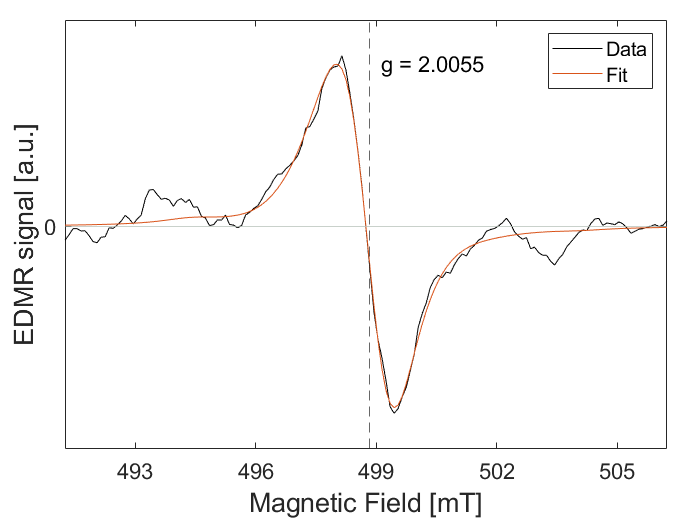

addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));
Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\New chip';
Opt.SFolder = "D:\Profile\qse\Files\_EDMRoC pinSC\Images";

load([Opt.LFolder, '\fit_chip']);

figure()
tL = tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact');
icw = 4; % Vbias = 1.5 V
grayC = '#b2beb5';
x_ = x(:, icw); y_ = y(:, icw); yFit_ = Fit(icw).fit;
ax = nexttile(1);
h(1) = plot(x_, y_, Color = 'black', DisplayName = 'Data');
hold on
h(2) = plot(x_, yFit_, DisplayName = 'Fit');

h(3) = xline(mhz2mt(14*1000, 2.0052), '--');
h(4) = yline(0, 'Color', grayC);

xticks(493:3:508); yticks(0);
xlim(setAxLim(x_, 0)); ylim(setAxLim(y_, 0.1));

Label3 = "g = 2.0055";
text(0.525, 0.9, Label3, 'Units', 'normalized', ...
    'FontSize', 13);
labelAxesFig(tL, "Magnetic Field [mT]", "EDMR signal [a.u.]")
legend([h(1) h(2)])
exportFig(gcf, Opt.SFolder, "_fit chip final", "pdf");
exportFig(gcf, Opt.SFolder, "_fit chip final", "png");

figure()
plot(x, y, x, scaleY(cumtrapz(y), y))
[~, id] = max(cumtrapz(y))
xline(x(id))
hold on
xnew = x(id:end);
ynew = cumtrapz(y(1:id));
ynewnew = flip(ynew);

plot(xnew, scaleY(ynewnew, y))

Exp.Range = [min(x) max(x)];
Sys = SysDb;
Vary = VaryDb;
Fit1comp = esfit(y, @pepper, {Sys, Exp}, {Vary});

## ppAmp vs Vbias

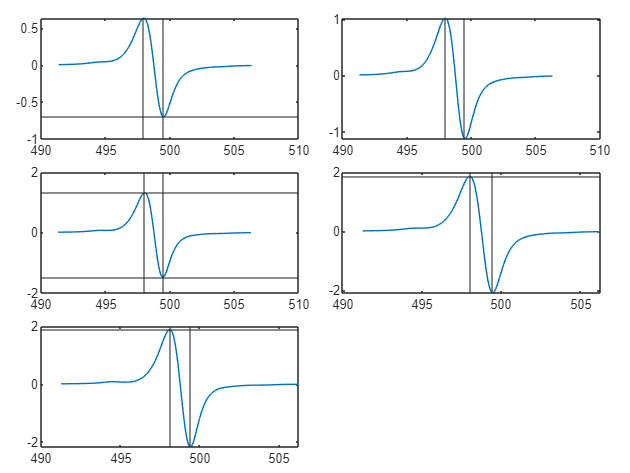

addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));
Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\New chip';
Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';
load([Opt.LFolder, '\fit_chip']);
[~, ncw] = size(x);

[ppAmp, yMax, yMin, xMax, xMin] = deal(zeros(1, ncw));

figure()
tL = tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact');
for icw = 1:ncw
    x_ = x(:, icw); y_ = y(:, icw);
    yFit_ = Fit(icw).fit;
    [ppAmp(icw), yMax(icw), yMin(icw), xMax(icw), xMin(icw)] = getPeakToPeakAmp(x_, yFit_);
    
    nexttile
    plot(x_, yFit_)
    hold on
    yline(yMax(icw)); yline(yMin(icw));
    xline(xMax(icw)); xline(xMin(icw));
end

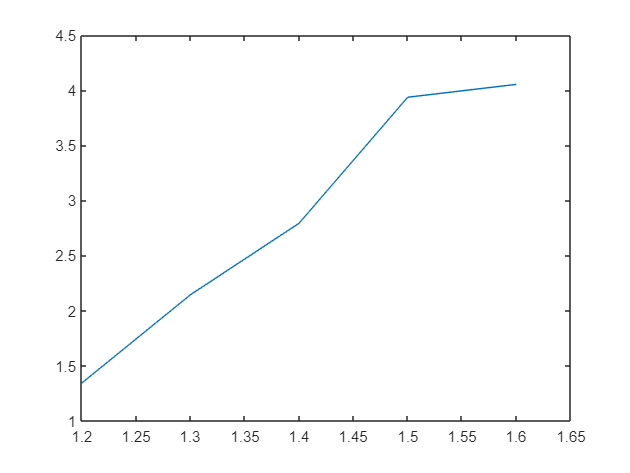

figure()
plot([1.2, 1.3, 1.4, 1.5, 1.6], ppAmp) % Last datapoint will be omitted

## Figure amplitude pp vs Vbias

Expected linear behavior.

Last datapoint (Vbias = 1.6 V) is taken out.

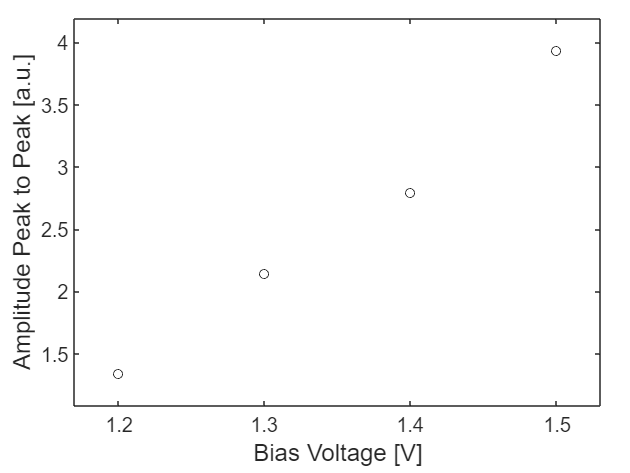

figure()
tL = tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact');

ax = nexttile(1);
Vbias = 1.2:0.1:1.5; ppAmpCut(1:end - 1);
h(1) = plot(Vbias, ppAmpCut, 'o', 'Color', 'black');


xticks(Vbias); 
xlim(setAxLim(Vbias, 0.1)); ylim(setAxLim(ppAmpCut, 0.1));

labelAxesFig(tL, "Bias Voltage [V]", "Amplitude Peak to Peak [a.u.]")

exportFig(gcf, Opt.SFolder, "_ppAmp", "pdf");

Graphics not exported


exportFig(gcf, Opt.SFolder, "_ppAmp", "png");

Graphics not exported
